% 清除内容
clear all
clc

%参数设置
p = [1, 1]* 9; % size of dictionary atoms
nA = prod(p); % number of Atoms
gap = 4; % control the overlapping
lambda = 50; % regularization parameter
tol = 1e-4; 
maxits = 1e4; % maximum number of interation

np = prod(p); % number of pixels in each patch

# task1 灰图字典

灰度图像的字典学习模型及算法

将参考示例代码，将他的功能封装成一个函数，输入灰度图片，和相应的参数，得到它对应的字典D,以及每步的误差有多大

% n = size(noise_image, 1:2);
% I = [1:gap:n(1)-p(1), n(1)-p(1)+1];
% J = [1:gap:n(2)-p(2), n(2)-p(2)+1];
% nP = numel(I)* numel(J); % total number of patches
% 
% lP = zeros(nP, 5); % location of each patch

[D_barbara, ek_barbara] = gray_image_dictionary('filename','barbara_512.png');      
fprintf('\n');
figure(002), clf;
semilogy(ek_barbara);

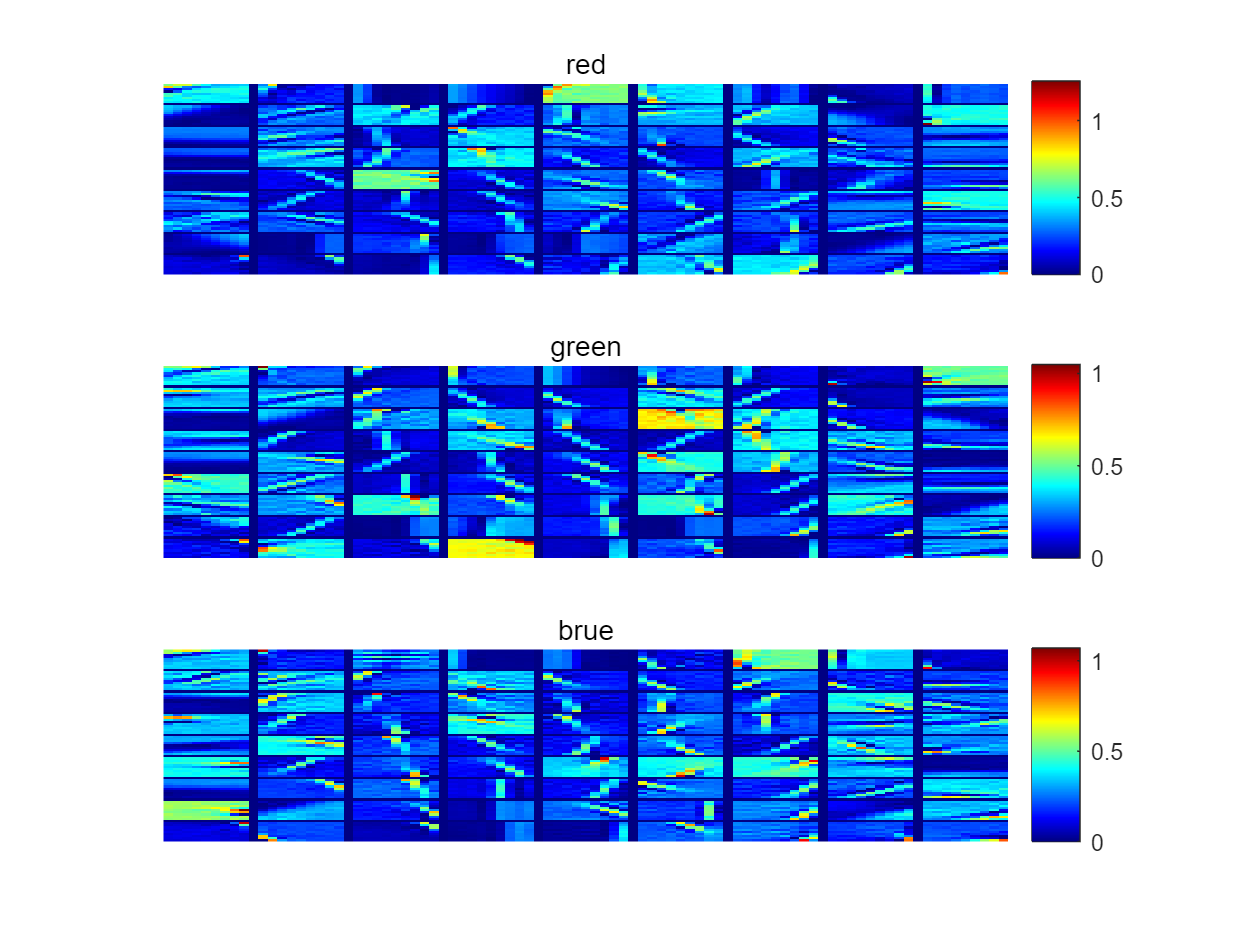

[D_lena, ek_lena] = gray_image_dictionary('filename','lena_512.png');

fprintf('\n');
figure(003), clf;
semilogy(ek_lena);

[D_cameraman, ek_cameraman] = gray_image_dictionary('filename','cameraman_512.png');
fprintf('\n');
figure(003), clf;
semilogy(ek_cameraman);

# Task2 彩图字典

彩色图像的字典学习模型及算法

[D_McM12, ek_McM12] = color_image_dictionary('filename','McM12.tif');
fprintf('\n');
figure(002), clf;
semilogy(ek_McM12);

Max difference between the values of patch mean value: 251.55...
000500, rel_error: 4.93e+00, obj_value: 2.6282e+08, l1_norm: 1.40e+08...
001000, rel_error: 1.02e+00, obj_value: 2.6292e+08, l1_norm: 1.40e+08...
001500, rel_error: 1.46e+00, obj_value: 2.6295e+08, l1_norm: 1.40e+08...
002000, rel_error: 2.58e-01, obj_value: 2.6299e+08, l1_norm: 1.40e+08...
002500, rel_error: 1.73e-01, obj_value: 2.6300e+08, l1_norm: 1.40e+08...
003000, rel_error: 1.17e-01, obj_value: 2.6301e+08, l1_norm: 1.40e+08...
003500, rel_error: 6.43e-02, obj_value: 2.6301e+08, l1_norm: 1.40e+08...
004000, rel_error: 4.78e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
004500, rel_error: 3.53e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
005000, rel_error: 2.59e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
005500, rel_error: 2.07e-02, obj_value: 2.6302e+08, l1_norm: 1.40e+08...
006000, rel_error: 1.97e-02, obj_value: 2.6303e+08, l1_norm: 1.40e+08...
006500, rel_error: 1.41e-02, obj_value: 2.6303e+08, l1_norm

plot_color_dictionary(D_McM12); %绘制彩色图片字典

# Task3 降噪

对18张图进行学习，利用学习到的词典进行降噪

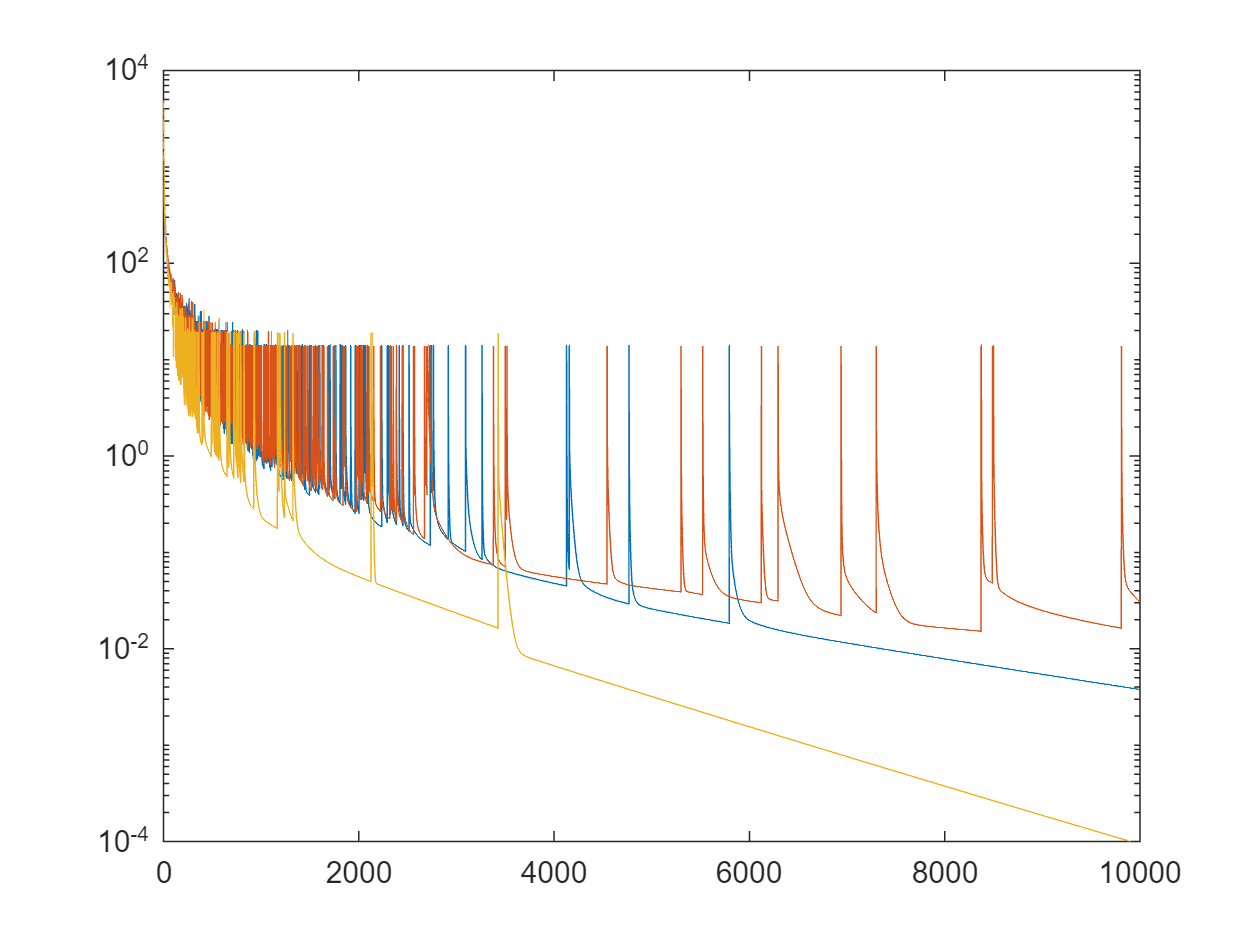

% load McM12_noise.mat u_n 
% McM12_noise = u_n;
% load D_McM12.mat D_McM12  % 不想重新算字典的话，可以用保存了的

filename = 'McM12.tif';
McM12 = double(imread(filename));

% 算出稀疏矩阵系数
[C_RGB, ek_lasso_RGB, mP_noise_RGB] = color_image_denoise('noise_image', ...
    McM12_noise, 'dictionary', D_McM12);

figure(006), clf;
semilogy(ek_lasso_RGB);

# 从噪点恢复原图

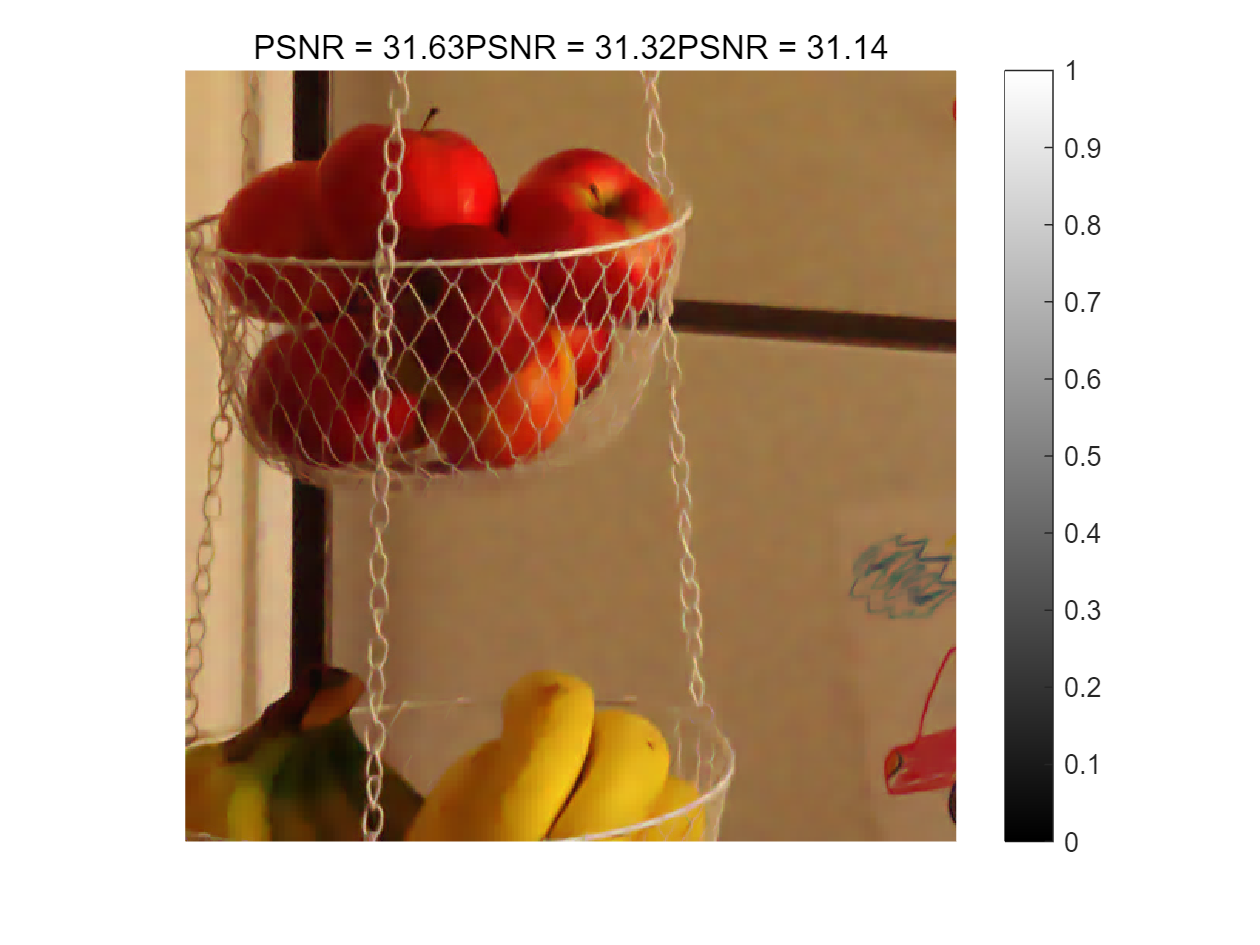

u_denoise_RGB = recover_color_image('noise_image', McM12_noise, 'dictionary', D_McM12, ...

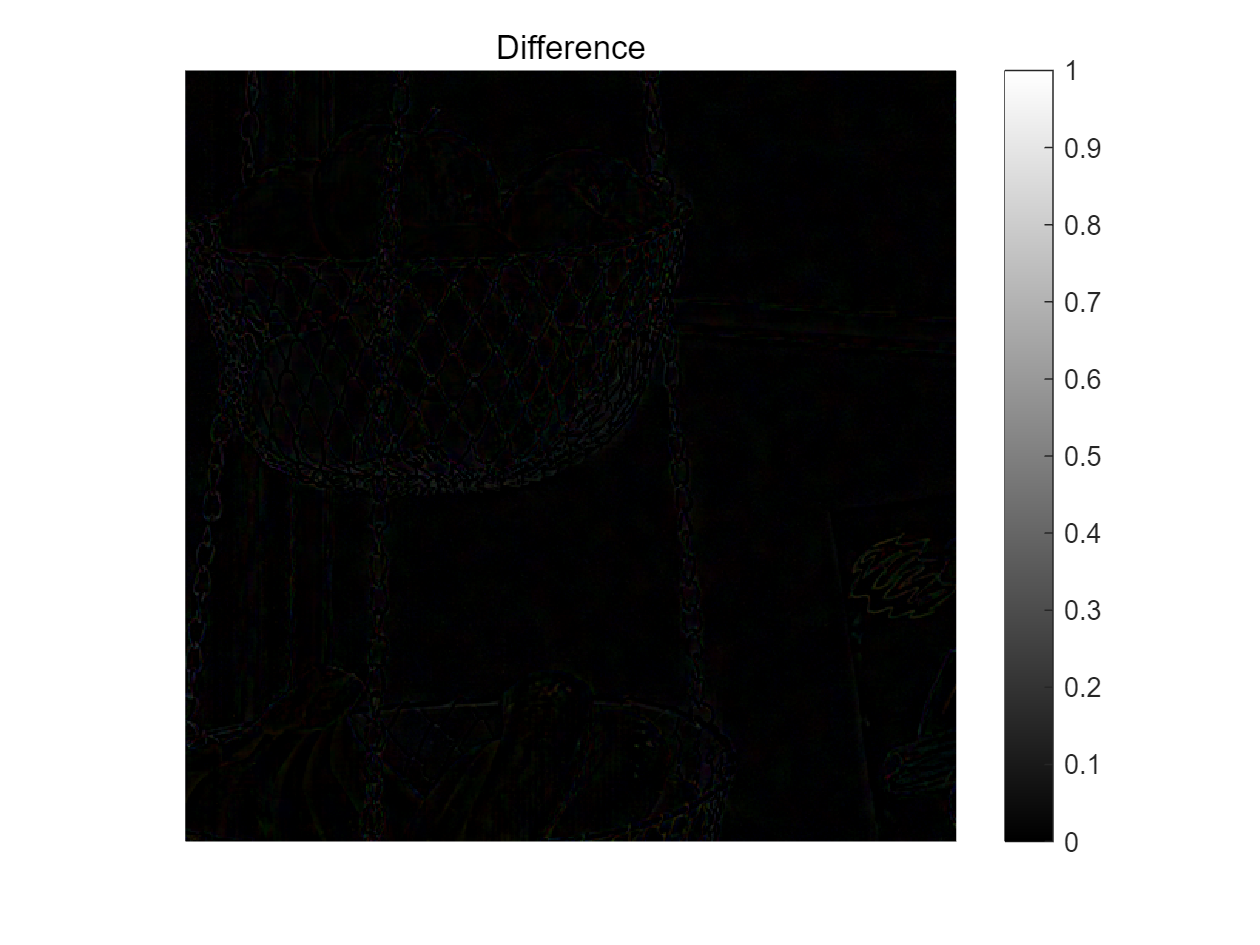

    'sparse_coefficient', C_RGB, 'mP_noise', mP_noise_RGB);

figure(007), clf;

000500, time: 03.52s, rel_error: 0.00e+00, obj_value: 0.00e+00...
001000, time: 07.08s, rel_error: 0.00e+00, obj_value: 0.00e+00...
000500, time: 03.46s, rel_error: 0.00e+00, obj_value: 0.00e+00...
001000, time: 06.92s, rel_error: 0.00e+00, obj_value: 0.00e+00...
000500, time: 03.47s, rel_error: 0.00e+00, obj_value: 0.00e+00...
001000, time: 06.96s, rel_error: 0.00e+00, obj_value: 0.00e+00...


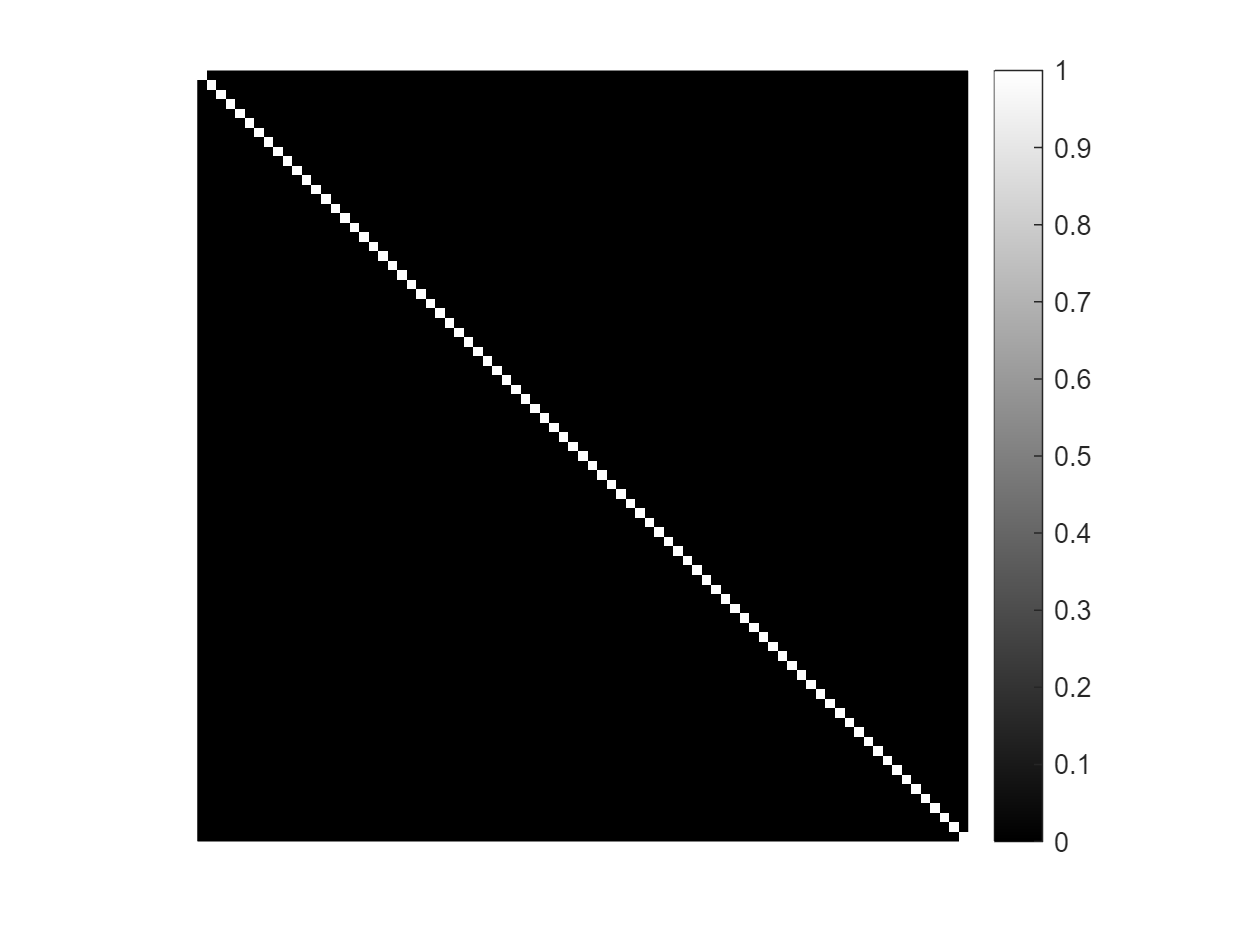

imgsc(u_denoise_RGB);
title(sprintf('PSNR = %.2f', psnr(McM12, u_denoise_RGB)));
figure(008), clf;

imgsc(u_denoise_RGB - McM12);
title('Difference');

# Task4 从噪点图找字典并恢复原图

[D_McM12_from_noise, ek_McM12_from_noise] = color_image_dictionary(McM12_noise);

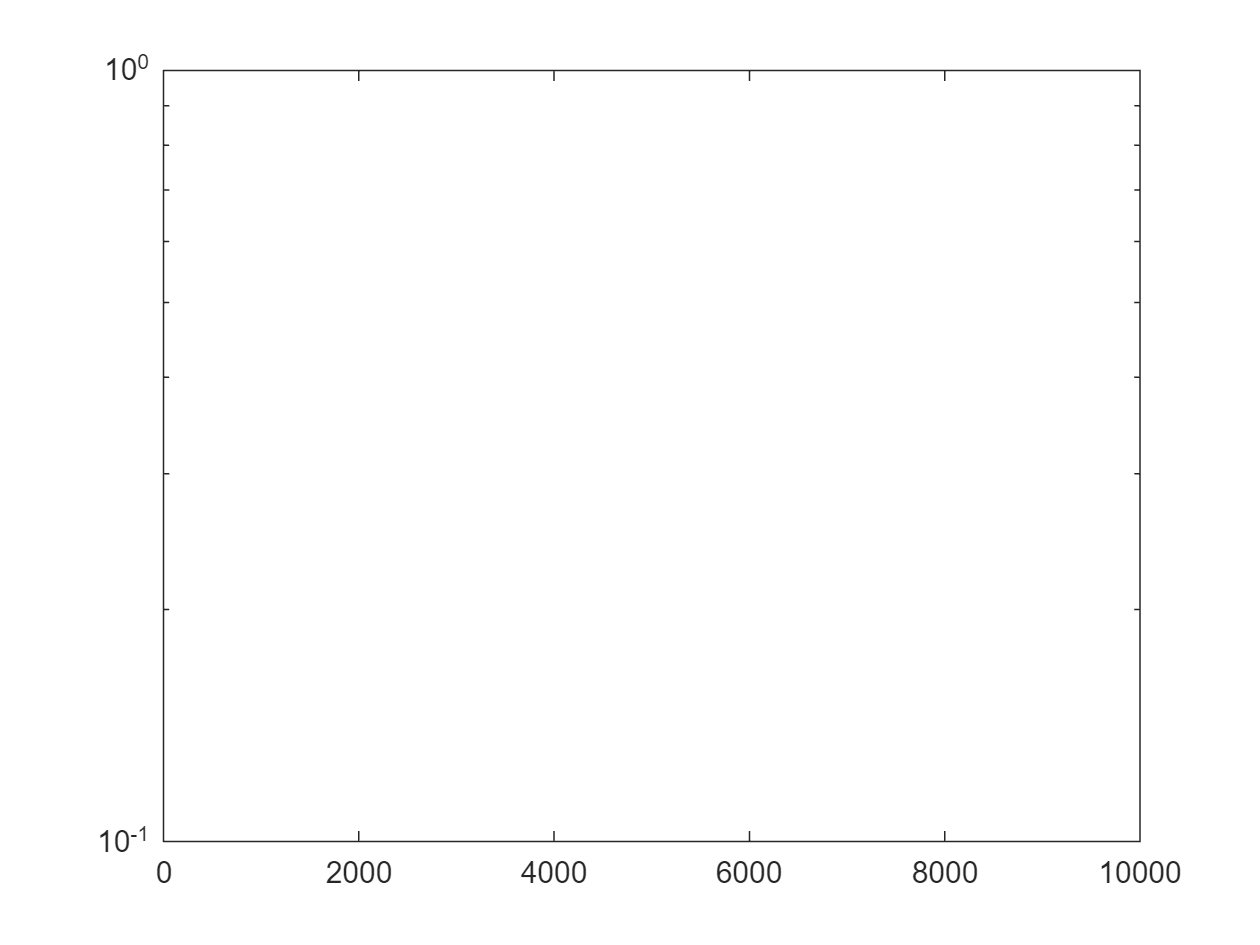


fprintf('\n');

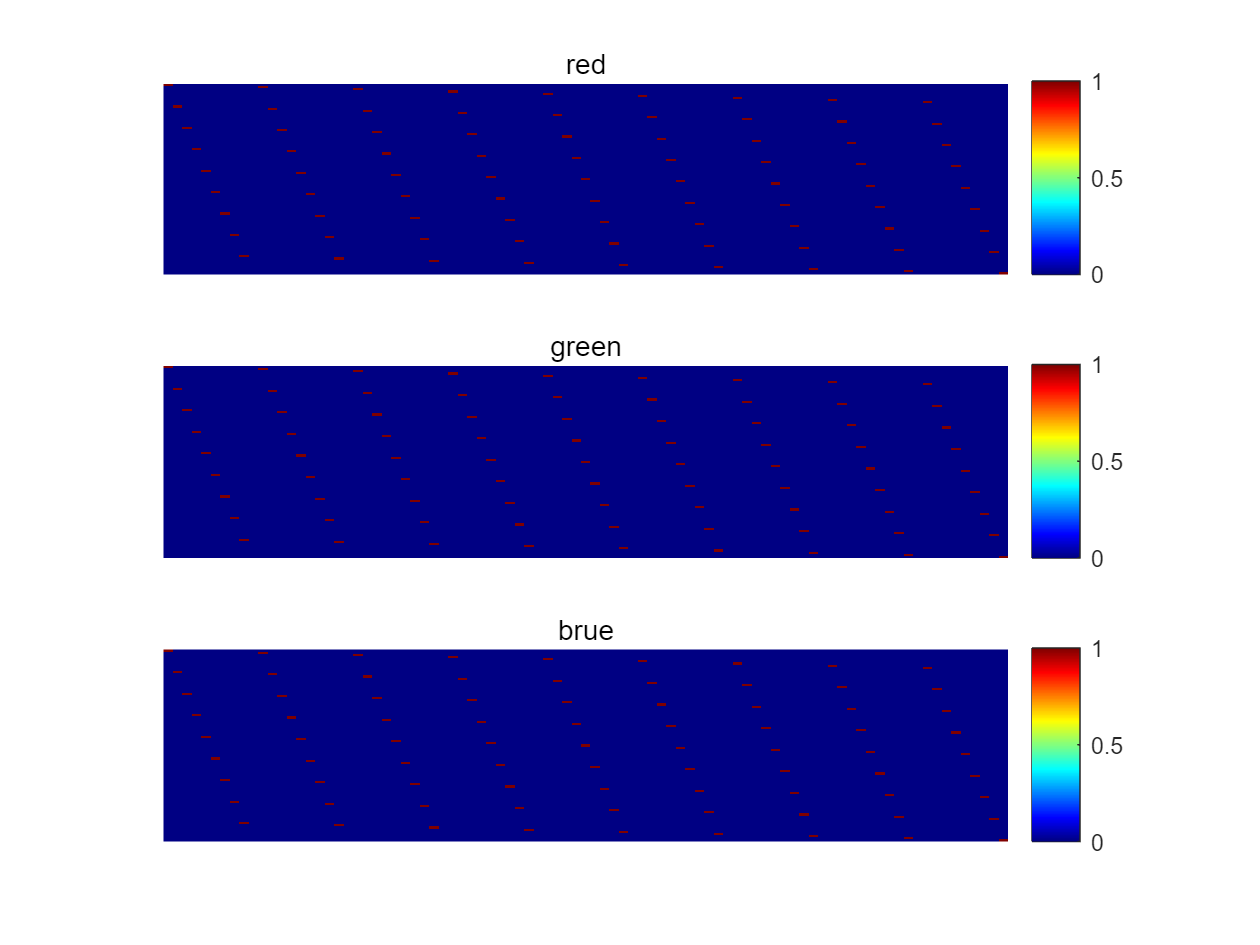

figure(002), clf;

semilogy(ek_McM12_from_noise);
plot_color_dictionary(D_McM12_from_noise); %绘制彩色图片字典
% 算出稀疏矩阵系数

Max difference between the values of patch mean value: 251.55...
Max difference between the values of patch mean value: 196.70...
Max difference between the values of patch mean value: 143.93...


[C_RGB_from_noise, ek_lasso_RGB_noise, mP_noise_RGB_noise] = color_image_denoise('noise_image', McM12_noise, ...
    'dictionary', D_McM12_from_noise);

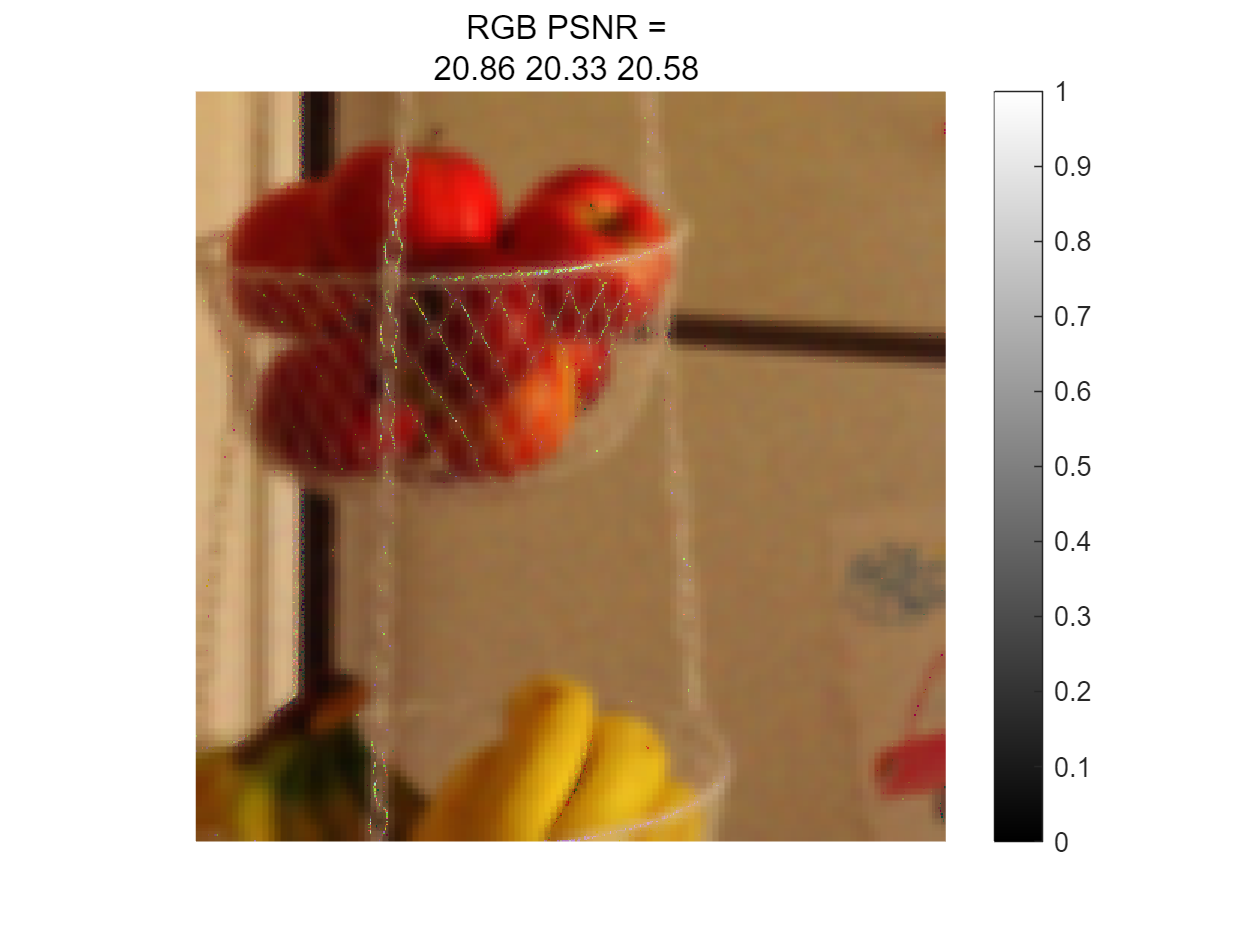

u_denoise_RGB_from_noise = recover_color_image('noise_image', McM12_noise, 'dictionary', D_McM12_from_noise, ...
    'sparse_coefficient', C_RGB_from_noise, 'mP_noise', mP_noise_RGB_noise);


figure(007), clf;
imgsc(u_denoise_RGB_from_noise);
title('RGB PSNR = ',sprintf('%.2f ', psnr(McM12_noise, u_denoise_RGB_from_noise)));

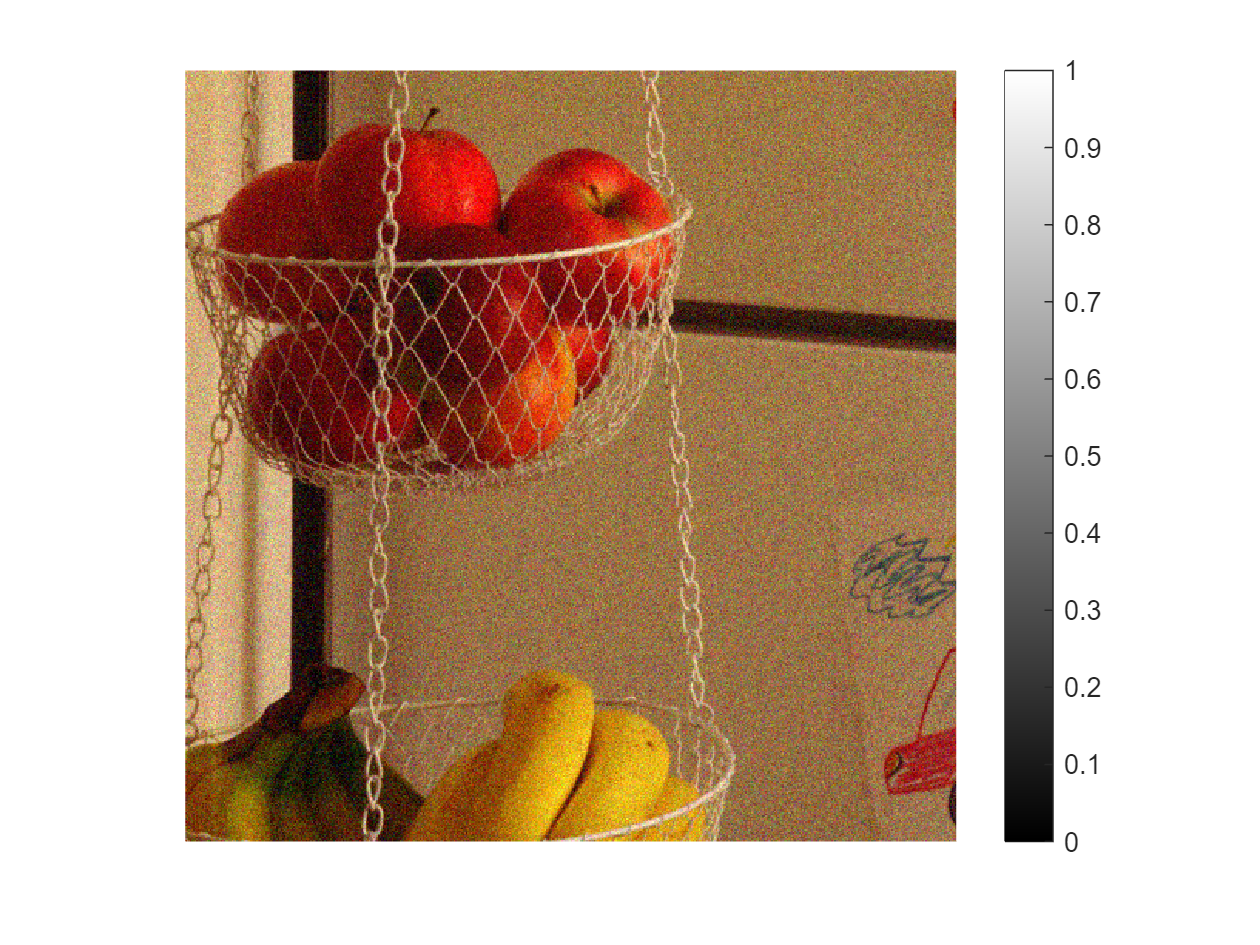

load McM12_noise.mat u_n 

McM12_noise = u_n;
imgsc(McM12_noise)